 close('all'); clear; clc;
setmadsympath();
sympref("FloatingPointOutput",false);

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

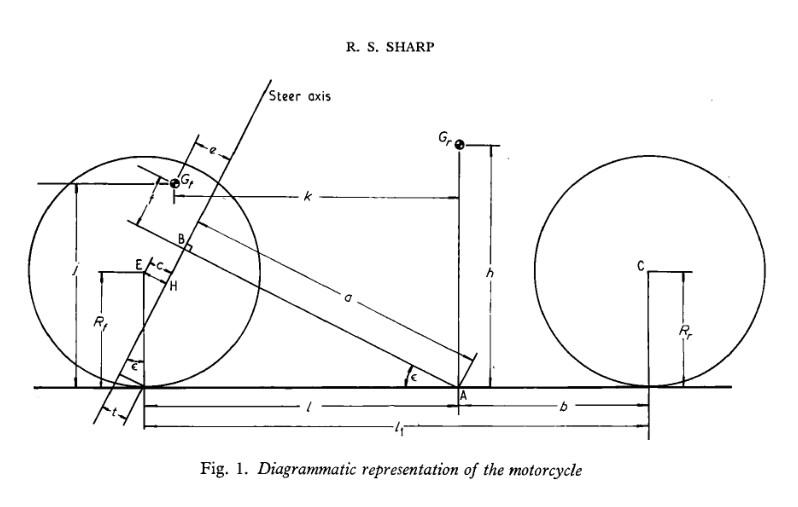

Create the caster frame:

caster = newParameters('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newParameters('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
l = solve(cos(caster) == a/(l + an/cos(caster)),l)

$$l = \frac{a-a_{n}}{\cos\left(\varepsilon \right)}$$

Locate the front wheel center $E$:

rf = newParameters('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom

$$rE = \left[\begin{array}{c} \frac{a-a_{n}}{\cos\left(\varepsilon \right)}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = simplify(expand(Ry(caster).'*E.posFrom(Pb)));
lx = rBE(1)

$$lx = r_{f}\,\sin\left(\varepsilon \right)-a_{n}$$

lz = rBE(3)

$$lz = -\frac{r_{f}\,{\cos\left(\varepsilon \right)}^{2}-a\,\sin\left(\varepsilon \right)+a_{n}\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newParameters('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gf = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gf.posFrom(Gfa) == 0,[a,f]);
lz_sub = simplify(expand(subs(lz,a,sol_af.a)))

$$lz\_sub = -\frac{j\,{\cos\left(\varepsilon \right)}^{2}-j+r_{f}\,{\cos\left(\varepsilon \right)}^{2}+a_{n}\,\sin\left(\varepsilon \right)+e\,\sin\left(\varepsilon \right)-k\,\cos\left(\varepsilon \right)\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

clearvars -except a an l rf caster lx lz e f j k sol_af;

## Joint coordinates

Translation of the motorcycle origin $A$:

t = sym('t');

q_names = {
    'x';
    'y';
    'psi';
    'varphi';
    'delta';
    'theta_r';
    'psi_f';
    'varphi_f';
    'theta_f'
    };

[x,y,yaw,lean,steer,pitch_r,yaw_f,lean_f,pitch_f] = ...
    dynamicVariables(q_names{:});

q_all = [x,y,yaw,lean,steer,pitch_r,yaw_f,lean_f,pitch_f];
q_dep = [yaw_f,lean_f];

q = GeneralizedCoordinates(q_all,q_dep);

## Force inputs

Rear and front tire lateral forces:

[Yr,Yf] = dynamicVariables('Y_r','Y_f');
Y = [Yr;Yf];

Throttle torque:

Mthrot = dynamicVariable('tau_theta_r');

Steering torque:

Msteer = dynamicVariable('tau_delta');
F = [Mthrot,Msteer].';

## Kinematics

### Rear chassis

Orientation:

N = Frame;
Nyaw = N.orientNew('z',yaw);
Nlean = Nyaw.orientNew('x',lean);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} \cos\left(\psi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\phi \right)\\ \sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & -\cos\left(\psi \right)\,\sin\left(\phi \right)\\ 0 & \sin\left(\phi \right) & \cos\left(\phi \right) \end{array}\right]$$

Position:

P0 = Point;
Pa = P0.locateNew(x.*N.x + y.*N.y);
h = newParameters('h');
Gr = Pa.locateNew(-h.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-h\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y+h\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -h\,\cos\left(\phi \right) \end{array}\right]$$

### Rear wheel

Orientation:

Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta_{r}\right)-\sin\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta_{r}\right)+\cos\left(\theta_{r}\right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ \cos\left(\theta_{r}\right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & \sin\left(\psi \right)\,\sin\left(\theta_{r}\right)-\cos\left(\psi \right)\,\cos\left(\theta_{r}\right)\,\sin\left(\phi \right)\\ -\cos\left(\phi \right)\,\sin\left(\theta_{r}\right) & \sin\left(\phi \right) & \cos\left(\theta_{r}\right)\,\cos\left(\phi \right) \end{array}\right]$$

Position:

[b,rr] = newParameters('b','r_r');
Wr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Wr.posFrom)

$$\left[\begin{array}{c} x-b\,\cos\left(\psi \right)-r_{r}\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y-b\,\sin\left(\psi \right)+r_{r}\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -r_{r}\,\cos\left(\phi \right) \end{array}\right]$$

#### Rear contact point

Cr = Wr.locateNew(rr*Nlean.z);
rWrCr = Cr.posFrom(Wr,Npitch_r);
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,\sin\left(\theta_{r}\right)\\ 0\\ r_{r}\,\cos\left(\theta_{r}\right) \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
Nsteer = Ncaster.orientNew('z',steer);

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

Nyaw_f = N.orientNew('z',yaw_f);
Nlean_f = Nyaw_f.orientNew('x',lean_f);
Npitch_f = Nlean_f.orientNew('y',pitch_f);

Position:

Wf = Pb.locateNew(lx.*Nsteer.x + lz.*Nsteer.z);

#### Front contact point

Cf = Wf.locateNew(rf.*Nlean_f.z);
rWfCf = Cf.posFrom(Wf,Npitch_f);
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,\sin\left(\theta_{f}\right)\\ 0\\ r_{f}\,\cos\left(\theta_{f}\right) \end{array}\right]$$

## Rigid bodies

### Rear chassis

mr = newParameters('m_r');
[Irx,Iry,Irz,Crxz] = ...
    newParameters('I_rx','I_ry','I_rz','C_rxz');
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
rear_chassis = Body(Nlean,Gr,Ir,mr);

### Rear wheel

iry = newParameters('i_ry');
Irw = inertia(0,iry,0);
rear_wheel = Body(Npitch_r,Wr,Irw,0);

### Front chassis

[mf,Ifx,Ifz] = newParameters('m_f','I_fx','I_fz');
If = inertia(Ifx,0,Ifz);
front_chassis = Body(Nsteer,Gf,If,mf);

### Front wheel

ify = newParameters('i_fy');
Ifw = inertia(0,ify,0);
front_wheel = Body(Npitch_f,Wf,Ifw,0);

## Tire equations

vCr = Twist(Pose(Nyaw,Cr)).TranslationalVelocity;
vCf = Twist(Pose(Nyaw_f,Cf)).TranslationalVelocity;

rl = newParameters('sigma');

C_names = {
    'C_r1';
    'C_r2';
    'C_f1';
    'C_f2'
    };

[Cr1,Cr2,Cf1,Cf2] = newParameters(C_names{:});

slip_r = atan(vCr(2)/vCr(1));
slip_f = atan(vCf(2)/vCf(1));

eqYr = vCr(1)*(Yr + Cr1*slip_r - Cr2*lean);
eqYf = vCf(1)*(Yf + Cf1*slip_f - Cf2*lean_f);
eqY = [
    rl*diff(Yr) + eqYr;
    rl*diff(Yf) + eqYf
    ];

## Forces and moments

### Rear tire

Zr = newParameters('Z_r');
rear_wheel.applyForce(Nyaw,Cr,Yr*N.y + Zr.*N.z);

### Front tire

Zf = newParameters('Z_f');
front_wheel.applyForce(Nyaw_f,Cf,Yf.*N.y + Zf.*N.z);

### Throttle torque

rear_wheel.applyMoment(Nlean,Mthrot.*N.y);
rear_chassis.applyMoment(Nlean,-Mthrot.*N.y);

### Steering torque

Csteer = newParameters('C_delta');
Mz = (Msteer - Csteer*diff(steer)).*N.z;
front_chassis.applyMoment(Nsteer,Mz);
rear_chassis.applyMoment(Nsteer,-Mz);

### Gravity

bodies = [
    rear_chassis;
    rear_wheel;
    front_chassis;
    front_wheel
    ];

g = newParameters('g');
fg = @(b)b.applyForce(N,b.MassCenter,(b.Mass*g).*N.z);
arrayfun(fg,bodies);

## Quasi-velocities

u_names = {
    'omega_varphi';
    'omega_delta';
    'omega_theta_r';
    'v_x';
    'v_y';
    'omega_psi';
    'omega_psi_f';
    'omega_varphi_f';
    'omega_theta_f'
    };

u_ind = dynamicVariables(u_names{:}).';
u = GeneralizedCoordinates(u_ind);

## Kinematic equations

va = Twist(Pose(Nyaw,Pa)).TranslationalVelocity;
pprint(va)

$$\left[\begin{array}{c} \dot{x}\,\cos\left(\psi \right)+\dot{y}\,\sin\left(\psi \right)\\ \dot{y}\,\cos\left(\psi \right)-\dot{x}\,\sin\left(\psi \right)\\ 0 \end{array}\right]$$

kdes = [
    u.All(1:3) - diff([lean,steer,pitch_r].',t);
    u.All(4:5) - va(1:2);
    u.All(6:end) - diff([yaw,yaw_f,lean_f,pitch_f].',t)
    ];

Kinematic jacobian:

Jk = KinematicJacobian(kdes,diff(q.All));
Jqd = simplify(expand(Jk.qd));
Ju = simplify(expand(Jk.u));

Kinematic rates:

qd = diff(q.All);
Jud = simplify(expand(subs(diff(Ju,t),qd,Ju*u.All)));

## Inertial forces

qdsub = Ju*u.All;
qddsub = Jud*u.All + Ju*diff(u.All);
ovars = [diff(qd,t);qd];
nvars = [qddsub;qdsub];

fJb = @(b)b.Twist.jacobian(qd);
fbQi = @(b)b.InertialForces;
fQi = @(b)subs(fJb(b).'*fbQi(b),ovars,nvars);
Qi = sum(cell2sym(arrayfun(fQi,bodies.',"uniform",0)),2);
Qi = simplify(expand(Qi));

[Mi,fi] = massMatrixForm(Qi,u.All);

## Constraints

### Holonomic

spin_x = simplify(expand(Nsteer.y(1) - Nlean_f.y(1)));
spin_z = simplify(expand(Nsteer.y(3) - Nlean_f.y(3)));

hc = [
    spin_z;
    spin_x
    ];

pprint(hc)

$$\left[\begin{array}{c} \cos\left(\delta \right)\,\sin\left(\phi \right)-\sin\left(\phi_{f}\right)+\sin\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\varepsilon \right)\\ \cos\left(\phi_{f}\right)\,\sin\left(\psi_{f}\right)-\cos\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\delta \right)\,\cos\left(\varepsilon \right)+\sin\left(\delta \right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\varepsilon \right) \end{array}\right]$$

### Nonholonomic

no_slip_r = noslip(rear_wheel,rWrCr);
no_slip_f = noslip(front_wheel,rWfCf);

nhc = [
    no_slip_r(1:2);
    no_slip_f(1:2)
    ];

### Jacobian

constraints = Constraints(hc,nhc);
A = jacobian(constraints.Nonholonomic,qd)*Ju;
A = simplify(expand(A));

## Constraint forces

M = [
    Mi,A.';
    A,zeros(size(A,1))
    ];

f = [
    fi;
    subs(diff(A,t),ovars,nvars)*qdsub
    ];

f = simplify(expand(f));

M0 = simplify(expand(subs(M,yaw,0)));